# Script para generar las funciones base tipo boostlet que se usaran en RIRIS

En RIRIs se usa {room}_tau{iscales}.mat con 

room: Balder, Freja, Munin

iscales: 2, 3, 4, 5

## genBoostlet function

[phi,KX,OM] = genBoostlet(N,a_j,theta_j,far_or_near,boost_type)

Usa MeyerWaveletsFunctions y MeyerScalingFunction

N = num de grid points

a_j = dilatacion

theta_j = angulo de la transf boostlet

far_or_near = 0 or 1 (fal field or near field)

boost_type = 1 or 2; 1 for scaling function; 2 for boostlet functions

% Ejemplo

N = 128; % Tamaño de la imagen NxN
S = 3; % numero de escalas (similar al tau en shearlets)
n_thetas = 10;
far_or_near = [0, 1];


[phi,KX,OM] = genBoostlet(N,S-1,0,0,1);

'Grid'

ans = 'Grid'

size(KX)

ans =    128   128


size(OM)

ans =    128   128



'phi'

ans = 'phi'

size(phi)

ans =    128   128


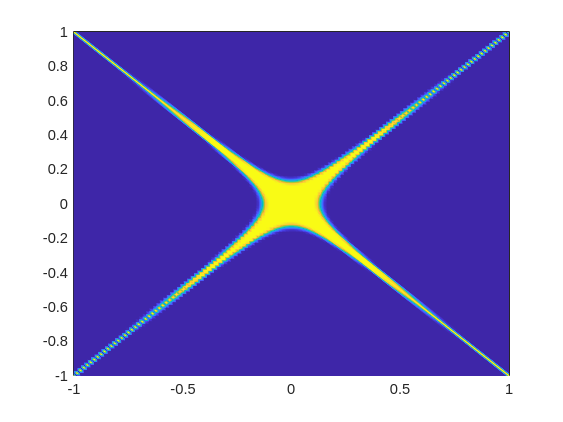

pcolor(KX, OM, phi)
shading interp

Hay un phi con boostlet_type=1 :

        phi = MeyerScalingFun(N,Ad);

Hay multiples phi con boostlet_type=2: 

        PHI_1 = MeyerWaveletFun(N,Ad);

        PHI_2 = MeyerScalingFun(N,Th);

        phi = PHI_1.*PHI_2;


% set dilation and boost levels
a_grid = 2.^(linspace(0,S-1,S));
theta_grid = linspace(-pi/2,pi/2,n_thetas); % hard-wired, should change if S changes!


Psi = [];
% Boostlet type 1 (Scaling function):
boost_type = 1;
Psi(:,:,1) = genBoostlet(N,S-1,0,0,boost_type);
cc=1;

% Boostlets type 2:
boost_type = 2;
for fnfn = far_or_near
    for aa = 1:length(a_grid)
        for thth = 1:length(theta_grid)
            % generate boostlet function
            [phi,~,~] = genBoostlet(N,a_grid(aa),theta_grid(thth),fnfn,boost_type);
            % compute (cc+1)-th boostlet coefficient and store
            cc = cc + 1;
            Psi(:,:,cc) = phi;
        end
    end
end

size(Psi)

ans =    128   128    61


filename = sprintf('boostlets_N_%i_S_%i_thetas_%i.mat', N, S, n_thetas)

filename = 'boostlets_N_128_S_3_thetas_10.mat'

save(filename, "Psi")


a = [0:8] 

a =      0     1     2     3     4     5     6     7     8


b = fftshift(a)

b =      5     6     7     8     0     1     2     3     4


c = ifftshift(a)

c =      4     5     6     7     8     0     1     2     3
